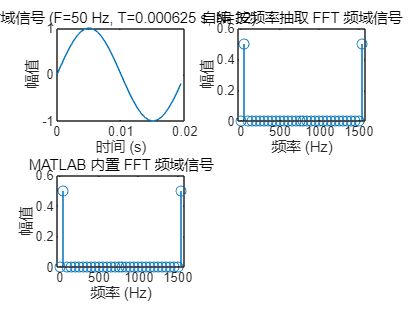

按频率抽取 FFT 与 MATLAB FFT 最大差异: 5.463e-15


% 基-2按频率抽取的FFT算法
function X = FFT_freq_extract(x)
    N = length(x);
    X = bit_reverse_order(x);  % 二进制反转顺序排列
    stages = log2(N);  % FFT 需要的阶段数

    % 基-2按频率抽取计算过程
    for s = 1:stages
        m = 2^s;
        W_m = exp(-2i*pi*(0:m/2-1)/m);  % 旋转因子
        for k = 0:(N/m - 1)
            for j = 1:m/2
                t = W_m(j) * X(k*m + j + m/2);
                u = X(k*m + j);
                X(k*m + j) = u + t;
                X(k*m + j + m/2) = u - t;
            end
        end
    end
end

% 二进制反转顺序排列
function X = bit_reverse_order(x)
    N = length(x);
    X = zeros(1, N);
    num_bits = log2(N);
    
    for n = 0:N-1
        reversed_n = bit_reverse(n, num_bits);
        X(reversed_n + 1) = x(n + 1);  % MATLAB 索引从 1 开始
    end
end

% 二进制反转
function r = bit_reverse(n, num_bits)
    r = 0;
    for i = 0:num_bits-1
        r = bitor(r, bitshift(bitand(n, 1), num_bits - 1 - i));
        n = bitshift(n, -1);
    end
end

% 比较按频率抽取 FFT 和 MATLAB 内置 FFT 结果
function compare_fft_freq_extract(F, T, N, zero_padding)
    % 生成信号
    t = (0:N-1) * T;
    x = sin(2*pi*F*t);
    
    % 补零选项
    if zero_padding
        x = [x, zeros(1, N)]; % 补零至2*N样点
        N = 2 * N; % 更新样点数
    end
    
    % 自编按频率抽取的 FFT
    X_custom_freq = FFT_freq_extract(x);
    
    % MATLAB 内置 FFT
    X_builtin = fft(x);
    
    % 频率轴
    f = (0:N-1) * (1/(N*T));
    
    % 绘制时域图
    figure;
    subplot(2,2,1);
    plot((0:N-1)*T, x);
    title(['时域信号 (F=', num2str(F), ' Hz, T=', num2str(T), ' s, N=', num2str(N), ')']);
    xlabel('时间 (s)');
    ylabel('幅值');

    % 绘制频域比较图
    subplot(2,2,2);
    stem(f, abs(X_custom_freq)/N);
    title('自编 按频率抽取 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    subplot(2,2,3);
    stem(f, abs(X_builtin)/N);
    title('MATLAB 内置 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    % 比较结果
    diff = max(abs(X_custom_freq - X_builtin));
    disp(['按频率抽取 FFT 与 MATLAB FFT 最大差异: ', num2str(diff)]);
end

% 测试并验证不同情况

% a) F=50Hz, N=32, T=0.000625s
compare_fft_freq_extract(50, 0.000625, 32, 0);

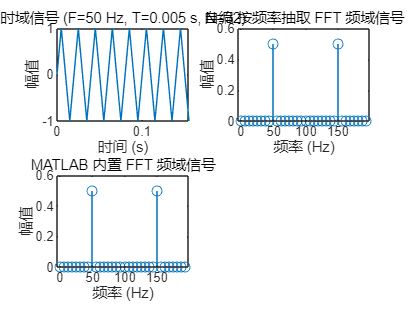

按频率抽取 FFT 与 MATLAB FFT 最大差异: 9.7972e-16



% b) F=50Hz, N=32, T=0.005s
compare_fft_freq_extract(50, 0.005, 32, 0);

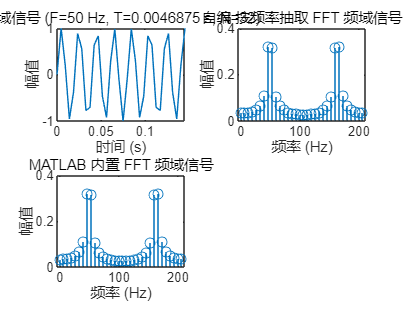

按频率抽取 FFT 与 MATLAB FFT 最大差异: 2.5121e-15



% c) F=50Hz, N=32, T=0.0046875s
compare_fft_freq_extract(50, 0.0046875, 32, 0);

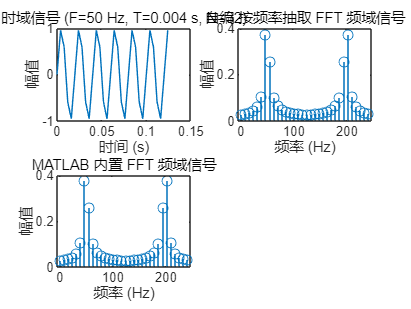

按频率抽取 FFT 与 MATLAB FFT 最大差异: 2.5121e-15



% d) F=50Hz, N=32, T=0.004s
compare_fft_freq_extract(50, 0.004, 32, 0);

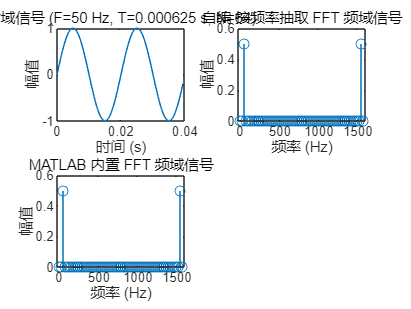

按频率抽取 FFT 与 MATLAB FFT 最大差异: 1.1416e-14



% e) F=50Hz, N=64, T=0.000625s
compare_fft_freq_extract(50, 0.000625, 64, 0);

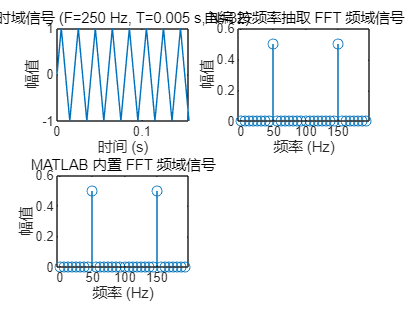

按频率抽取 FFT 与 MATLAB FFT 最大差异: 9.7972e-16



% f) F=250Hz, N=32, T=0.005s
compare_fft_freq_extract(250, 0.005, 32, 0);

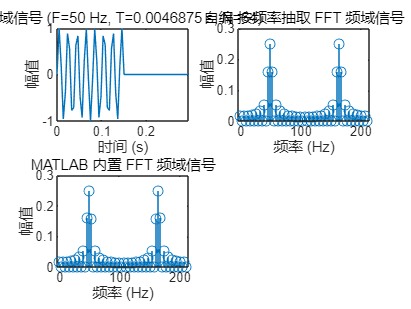

按频率抽取 FFT 与 MATLAB FFT 最大差异: 5.8344e-15



% g) F=50Hz, N=32, T=0.0046875s, 补零
compare_fft_freq_extract(50, 0.0046875, 32, 1);